## Variables tuning

In this section there is the code configuration. 

%%% PRINT VARIABLES %%%
printTrainingSet = 0; % Print random images of the training set
printTestSet = 0; % Print random images of the predicted set
printConfMatr = 1; % Print the confusion matrix

%%% OTHER VARIABLES %%%
numClasses = 16;

## Load Data

Load the training, test set as an image datastore. `imageDatastore` automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore lets you store large image data, including data that does not fit in memory. After split the training set into Training and Validation set.

imdsTrain = imageDatastore('TrainingSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imageDatastore('ValidationSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('TestSet','IncludeSubfolders',true,'LabelSource','foldernames');
numTrainImages = numel(imdsTrain.Labels);

### Print some images of the training set

In this section if the previous variable is true the code prints random training set images.

if printTrainingSet == 1
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i));
        imshow(I)
    end
end

## Load pretrained Network

tic;
net = alexnet;

## Resize the images

The networks require different input size, in this section the image will be resized to fit the first input layer. To automatically resize the training and test images before they are input to the network, create augmented image datastores, specify the desired image size, and use these datastores as input arguments to `activations`.

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);
YTrain = imdsTrain.Labels;
YTest = imdsTest.Labels;
YTrain = double(YTrain(:,1)) -1;
YTest = double(YTest(:,1)) -1;

## Fine-Tuning

We take all the layers except the last 3. The last three layers of the pretrained network are configured for 1000 classes. These three layers must be fine-tuned for the new classification problem.

After composing the network with the old and the modified layers. The last three layers have been replaced with a fully connected layer, a softmax layer, and a classification output layer. Set the fully connected layer to have the same size as the number of classes in the new data. To learn faster in the new layers than in the transfered layers, increase the `WeightLearnRateFactor` and `BiasLearnRateFactor` values of the fully connected layer.

freezedLayers = net.Layers(1:end-3);
layers = [
    freezedLayers
    fullyConnectedLayer(numClasses, ...
        'WeightLearnRateFactor',20, ...
        'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## Tune the training options

Specify the training options. For transfer learning, keep the features from the early layers of the pretrained network (the transferred layer weights). Train the network for a few epochs. Specify the mini-batch size and validation data.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',100, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Train the network

Train the network using the training set, the layers and the options configured before.

netTransfer = trainNetwork(augimdsTrain,layers,options);

## Classification

[YPred,scores] = classify(netTransfer,augimdsTest);
YPred = double(YPred(:,1)) -1;

## Show images

This portion of code shows 12 random images of the test set. For each of them it shows the number of the image, the prediction of the model and the correct class.

if printTestSet == 1
    idx = randi([1 3077],1,12);
    % idx = [];
    figure
    for i = 1:numel(idx)
        subplot(3,4,i)
        I = readimage(imdsTest,idx(i));
        label = YPred(idx(i));
        corr = YTest(idx(i));
        imshow(I)
        title("#: "+idx(i)+" / Predicted: "+label+" / Correct: "+corr)
    end
end

## Confusion Matrix

Plot the confusion matrix. If it is too small open it on a new figure.

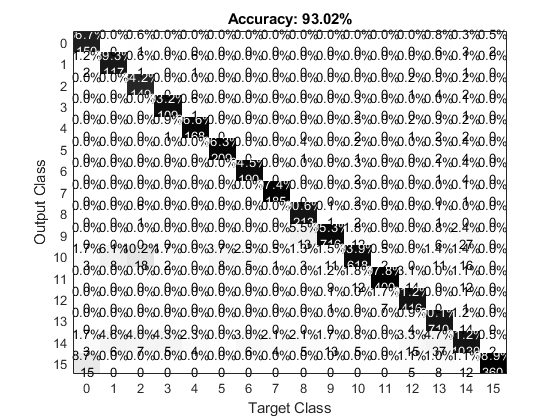

if printConfMatr == 1
    cm = confusionmat(YPred, YTest);
    labels = {0,1,2,3,4,5,6,7,8,9,10,11,12,13,14,15};
    figure
    plotConfMat(cm,labels)
end

## Results

time = toc;
diff = numel(find(YPred~=YTest));
[M,N] = size(YPred);
tp = M-diff;
accuracy = round(mean(YPred == YTest)*100,2);
disp('Accuracy: '+string(accuracy)+"% - Time Elapsed: "+time+" s - True Positive vs Total: "+tp+"/"+M);

Accuracy: 93.02% - Time Elapsed: 752.5325 s - True Positive vs Total: 5740/6171
